MEM703039 - KỸ THUẬT ROBOT

LỚP: N01.TH1

Thực hành: Lab 3

Mã số sv:

Họ và tên:

clear all
clc

Tạo mảng - Array

a = [1 2 3 4]

a =      1     2     3     4


b = a'

b =      1
     2
     3
     4


a1 = [1 3 5; 2 4 6; 7 8 10]

a1 =      1     3     5
     2     4     6
     7     8    10


A = a*3

A =      3     6     9    12


Ma trận nghịch đảo  - invert

p = a1*inv(a1)

p =     1.0000    0.0000   -0.0000
         0    1.0000   -0.0000
         0    0.0000    1.0000


Chú ý phép nhân ma trận 

p1 = a1*a1 % nhân theo quy tắc

p1 =     42    55    73
    52    70    94
    93   133   183


p2 = a1.*a1 % Nhân từng phẩn từ

p2 =      1     9    25
     4    16    36
    49    64   100


Các lệnh khác trên ma trận

p3 = [p1,p2] % ghép ma trận

p3 =     42    55    73     1     9    25
    52    70    94     4    16    36
    93   133   183    49    64   100


p4 = [p1; p2] % ghép ma trận

p4 =     42    55    73
    52    70    94
    93   133   183
     1     9    25
     4    16    36
    49    64   100


p5 = p4(3,3) % trích xuất 1 phần tử

p5 = 183

% phần tử hàng 3, cột 3 của p4
p6 = p4(:,3) % lấy toàn bộ cột 3

p6 =     73
    94
   183
    25
    36
   100


p7 = p4(2,:) % lấy toàn bộ hàng 2

p7 =     52    70    94


Tạo mảng nhanh

Cách 1: sử dụng cú pháp: (Giá trị đầu tiên: khoảng cách: Giá trị cuối)

Cách 2: lệnh linspace(Giá trị đầu, Giá trị cuối, số phần tử)

A = 0: 1: 100 % Cách 1

A =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


B = linspace(0,100,100) % Cách 2 - linear space

B =          0    1.0101    2.0202    3.0303    4.0404    5.0505    6.0606    7.0707    8.0808    9.0909   10.1010   11.1111   12.1212   13.1313   14.1414   15.1515   16.1616   17.1717   18.1818   19.1919   20.2020   21.2121   22.2222   23.2323   24.2424   25.2525   26.2626   27.2727   28.2828   29.2929   30.3030   31.3131   32.3232   33.3333   34.3434   35.3535   36.3636   37.3737   38.3838   39.3939   40.4040   41.4141   42.4242   43.4343   44.4444   45.4545   46.4646   47.4747   48.4848   49.4949


Bài tập 1:

Tạo mảng gồm có 10 000 phần tử, có giá trị cách đều trong khoảng [-pi, pi]

- Vẽ đồ thị x = sin(t)

- Vẽ đồ thị y = 2*cos(3*t) trên cùng đồ thị với ý (1)

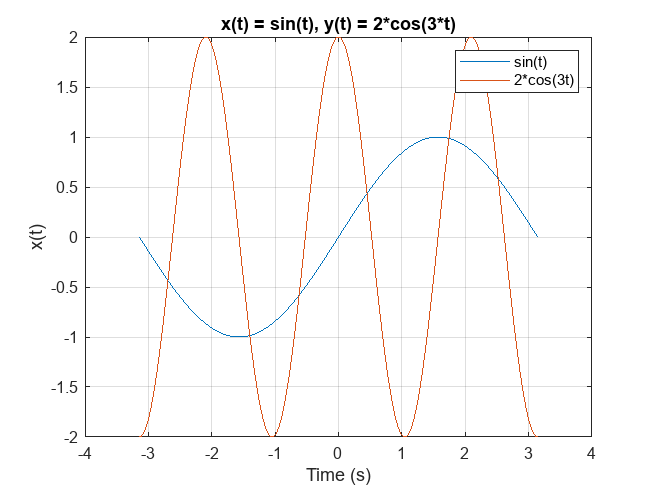

i = 1000;
t = linspace(-pi, pi, i);
x_t = sin(t);
plot(t,x_t) % Vẽ đồ thị 2D

grid on % Bật chế độ lưới (grid)
hold on % giữ nguyên đồ thị
y = 2*cos(3*t);
plot(t,y);
xlabel("Time (s)") % Tạo nhãn (tên) trục x
ylabel("x(t)") % Tạo nhãn (tên) trục y
title("x(t) = sin(t), y(t) = 2*cos(3*t)") % Tiêu đề của hình
legend("sin(t)", "2*cos(3t)")

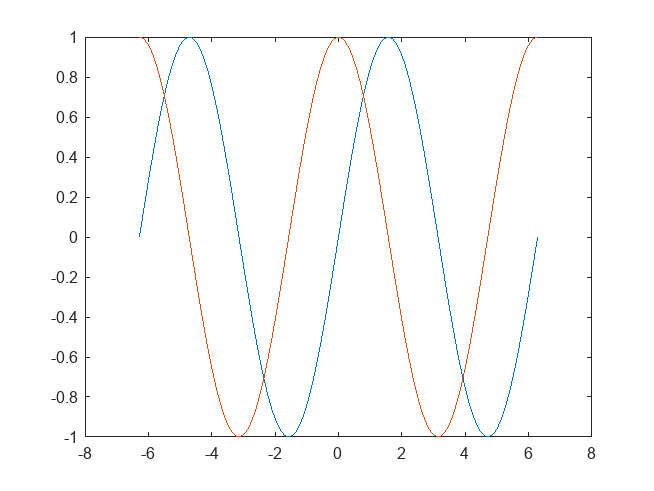

x = linspace(-2*pi,2*pi);
y1 = sin(x);
y2 = cos(x);

figure
plot(x,y1,x,y2)

5^3

ans = 125

25^2

ans = 625

sqrt(25) % sqrt = squared root of = căn bậc 2

ans = 5

125^(1/3) 

ans = 5

25^(1/2)

ans = 5

# mport data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 16-Sep-2024 10:07:00

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 11);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "GyroscopeXdegs", "GyroscopeYdegs", "GyroscopeZdegs", "AccelerometerXg", "AccelerometerYg", "AccelerometerZg", "MagnetometerXuT", "MagnetometerYuT", "MagnetometerZuT", "BarometerhPa"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable("C:\Users\Admin\Dropbox\0. Phenikaa Uni\1. Giao trinh\9. Ky thuật Robot\3. Bài giảng TH\sensors.csv", opts);

## Convert to output type

Times = tbl.Times;
GyroscopeXdegs = tbl.GyroscopeXdegs;
GyroscopeYdegs = tbl.GyroscopeYdegs;
GyroscopeZdegs = tbl.GyroscopeZdegs;
AccelerometerXg = tbl.AccelerometerXg;
AccelerometerYg = tbl.AccelerometerYg;
AccelerometerZg = tbl.AccelerometerZg;
MagnetometerXuT = tbl.MagnetometerXuT;
MagnetometerYuT = tbl.MagnetometerYuT;
MagnetometerZuT = tbl.MagnetometerZuT;
BarometerhPa = tbl.BarometerhPa;

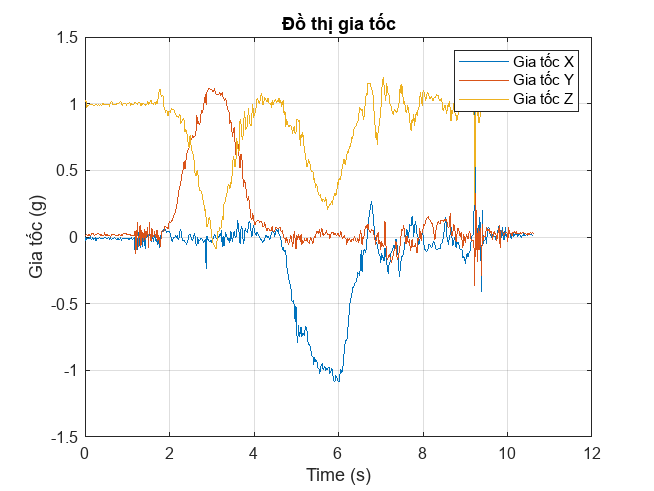

plot(Times, AccelerometerXg)
hold on
plot(Times, AccelerometerYg)
plot(Times, AccelerometerZg)
xlabel("Time (s)") % Tạo nhãn (tên) trục x
ylabel("Gia tốc (g)") % Tạo nhãn (tên) trục y
title("Đồ thị gia tốc") % Tiêu đề của hình
grid on 
legend("Gia tốc X", "Gia tốc Y", "Gia tốc Z")
hold off

Bài tập về nhà

Vẽ 3 đồ thị :

- Gia tốc tịnh tiến X Y Z

- Vận tốc góc quay quanh X Y Z

- Giá trị của từ trường X Y Z

- Xác định các giá trị lớn nhất địa phương (local peak) 

Yêu cầu: Chú thích rõ ràng

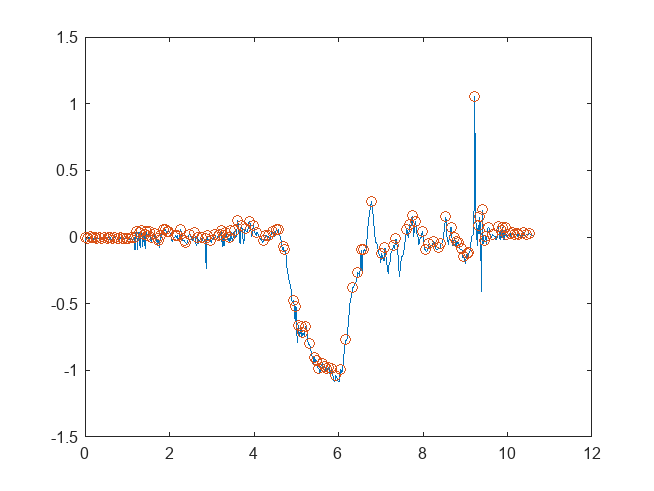

[pks,AccX] = findpeaks(AccelerometerXg);
plot(Times, AccelerometerXg)
hold on
plot(Times(AccX), pks,"o")

 LAB 3